% load WEC intrinsic impedance model
clear
clf
mf = load('waveBot_heaveModel.mat');
Zi = mf.Zi_frf(60:end,1);
Hex = mf.H_frf(60:end,1);
f = mf.f(60:end,1);
w = 2*pi*f;
dw = w(2)-w(1);

Ri = real(Zi);  % intrinsic resistance
Xi = imag(Zi);  % intrinsic reactance

## Sea state selection

We must define a sea state on which perform the analysis.

wave_type = "JS";  % select type of excitation
Tp = 2.5; % Wave Period (Peak period for Jonswap)
Hs = 1.25; % wave Height
gamma  = 3; % peakiness factor (for Jonswap)


$$S(\omega)=\frac{\alpha g^2}{\omega^5}\exp\left[-\frac{5}{4}\left(\frac{\omega_p}{\omega}\right)^4\right]\gamma^r\$$


where $r=\exp\left[-\frac{(\omega-\omega_p)^2}{2\sigma^2\omega_p^2}\right]$

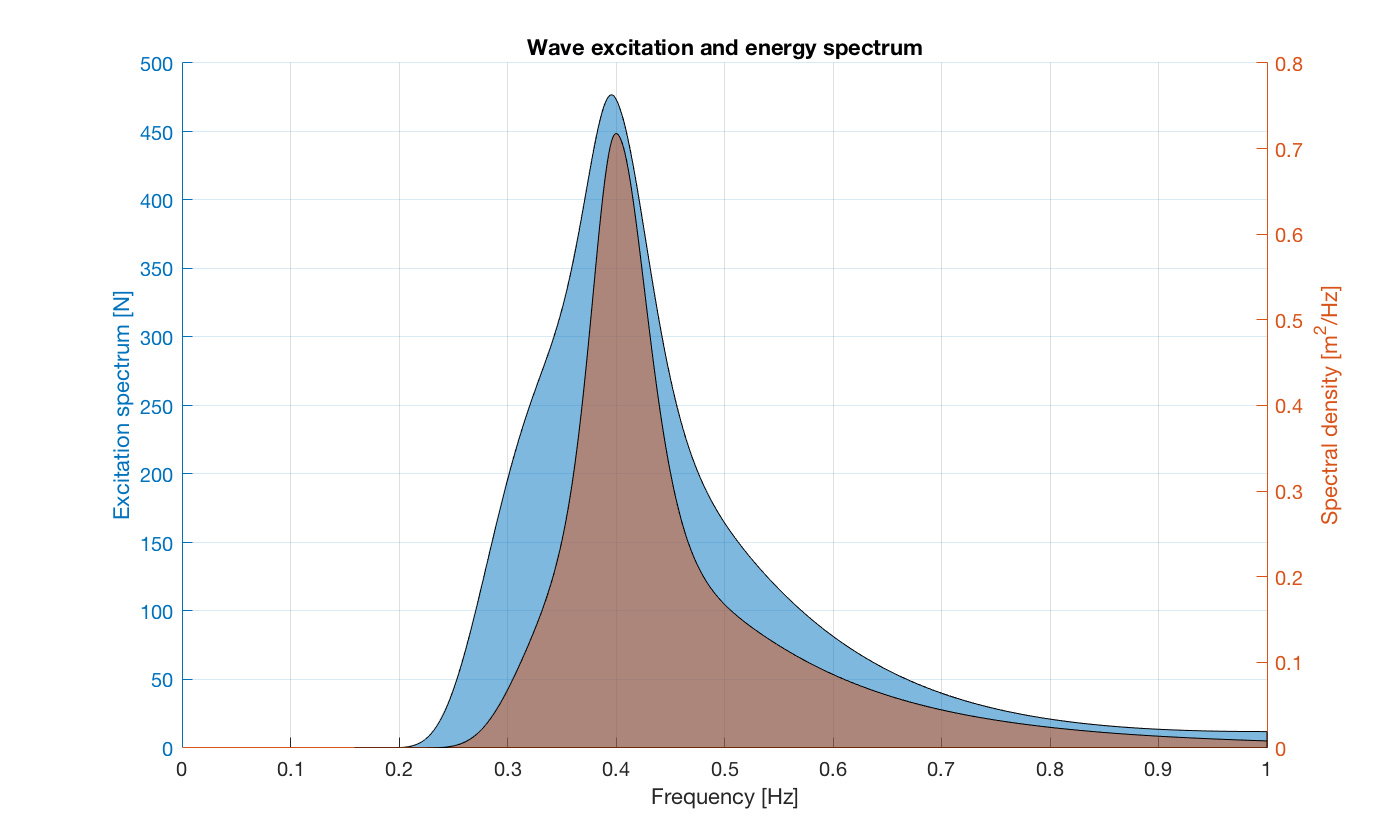


fig = figure;
fig.Position = fig.Position .* [1 1 1.25 1];
switch wave_type
    
    case 'JS'
        
        warning('off','WAFO:MKJONSWAP')
        
        S = jonswap(w, [Hs, Tp, gamma]);    % Wave energy density spectrum
        A = sqrt(2*dw*S.S(:));              % wave amplitude spectrum
        Fe = A .* Hex(:);                   % excitation spectrum
        
        hold on
        grid on
        
        yyaxis right
        ylabel('Spectral density [m^2/Hz]')
        area(f, 2*pi*S.S, 'facealpha',0.5)
        
        yyaxis left
        area(f, Fe, 'facealpha',0.5)
        
        warning('on','WAFO:MKJONSWAP')
        
    case 'Mono'
        
        f0 = floor(1/Tp*1e3)/1e3;
        [~,idx] = min(abs(f-f0));
        Fe = zeros(size(Hex));
        Fe(idx) = Hex(idx) * Hs/2; % Excitation force
        
        stem(f, Fe)
        
    case 'RAO'
        
        A = ones(length(f),1);
        Fe = A .* Hex(:);
        
        plot(f, Fe)
        
    otherwise
        error('Invalid wave type')
end

xlim([0, 1])

ylabel('Excitation spectrum [N]')
xlabel('Frequency [Hz]')
title('Wave excitation and energy spectrum')

## WEC Co-design optimization

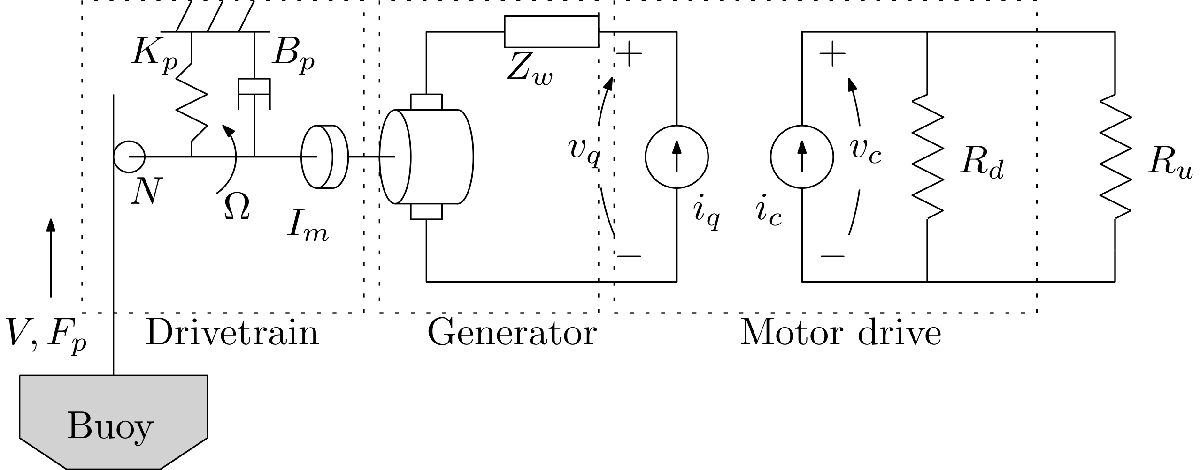

If we assume that perfect load matching is achieved, we can define the overall efficiency of the system as

$\eta = \frac{R_i}{\frac{3}{2}\frac{R_w}{K_t^2 N^2}|N^2 Z_d + Z_i|^2 + (N \, R_d + R_i)}$,

where the following variables are employed.

- Intrinsic resistance: $R_i = \Re\left\{ Z_i \right\}$

- Motor winding resistance: $R_w$

- Motor torque constant: $K_t$

- Gear ratio: $N$

- Drive train impedance: $Z_d$

- Intrinsic impedance: $Z_i$

- Drive train damping: $R_d$

We can thus perform an optimization to maximize electrical power at the load by manipulating the controller gains and the PTO parameters. 

 

N =9; N_opt_flag = true; N_bnds = [ 1, 10 ]; % gear ratio
Kt =10; Kt_opt_flag = false; Kt_bnds = [ 3, 4 ];% Generator torque constant
Rw =0.5; Rw_opt_flag = false; Rw_bnds = [ 3, 4 ];% Generator winding resistance
Lw =0; Lw_opt_flag = false; Lw_bnds = [ 3, 4 ];% Generator winding inductance
Id =2; Id_opt_flag = false; Id_bnds = [ 1, 4 ];% Drivetrain total moment of inertia (including generator's rotor)
Bd =0.4; Bd_opt_flag = false; Bd_bnds = [ 3, 4 ];% Drivetrain friction
Kd =48; Kd_opt_flag = false; Kd_bnds = [ -1000000000000   , 1000000000000 ];% Drivetrain spring coefficient (between shaft and reference/ground)

PTO_param_names = {'N','Kt','Rw','Lw','Id','Bd','Kd'};
PTO_param_mask = [N_opt_flag, Id_opt_flag, Bd_opt_flag, Kd_opt_flag, Kt_opt_flag, Rw_opt_flag, Lw_opt_flag];
PTO_bounds = [N_bnds(:), Id_bnds(:), Bd_bnds(:), Kd_bnds(:), Kt_bnds(:), Rw_bnds(:), Lw_bnds(:)];
PTO_param_lb = PTO_bounds(1,PTO_param_mask);
PTO_param_ub = PTO_bounds(2,PTO_param_mask);

PTO_params = [N, Id, Bd, Kd, Kt, Rw, Lw];

% generate an initial guess
x0 = [ones(1,sum(PTO_param_mask)), zeros(1,2)];
lb = [PTO_param_lb, -1*inf(1,2)];
ub = [PTO_param_ub, inf(1,2)];

P0 = co_optimize_oneDOF_PTO_power(x0, PTO_param_mask, PTO_params, w, Zi, Fe);

coOpt_obj_fun = @(x) co_optimize_oneDOF_PTO_power(x, PTO_param_mask, PTO_params, w, Zi, Fe);

options = optimoptions('fmincon','MaxFunctionEvaluations',1e6, 'MaxIterations', 1e6);
[y,fval] = fmincon(coOpt_obj_fun, x0, [], [], [], [],...
    lb, ub, [], options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


P_ub = 1/8*abs(Fe).^2 ./ Ri;    % Power upper bound
P_ub_tot = sum(P_ub);

PTO_params(PTO_param_mask) = y(1:sum(PTO_param_mask));
[P_tot, P_o, Z_L, Z_PTO, C] = co_optimize_oneDOF_PTO_power(y, PTO_param_mask, PTO_params, w, Zi, Fe);
assert(P_tot==fval)
eta_o = P_o ./ P_ub;
overall_eff = -1*P_tot/P_ub_tot;

T = table([PTO_param_lb(PTO_param_mask),nan(1,2)]',...
    [PTO_param_ub(PTO_param_mask),nan(1,2)]',...
    y',...
    'VariableNames',{'LowerBound','UpperBound','Optimal'},...
    'RowNames',[PTO_param_names(PTO_param_mask),'Kd','Kp']);

fprintf('Optimal parameters\n\n'), disp(T)

Optimal parameters

          LowerBound    UpperBound    Optimal
          __________    __________    _______

    N          1            10             10
    Kd       NaN           NaN           3762
    Kp       NaN           NaN        -6367.7




fprintf('Max theoretical power [W]:\t%.2e',P_ub_tot)

Max theoretical power [W]:	1.25e+03

fprintf('Total power [W]:\t\t%.2e',-1*P_tot)

Total power [W]:		7.19e+02

fprintf('Overall efficiency [ ]:\t\t%.2f',overall_eff)

Overall efficiency [ ]:		0.57

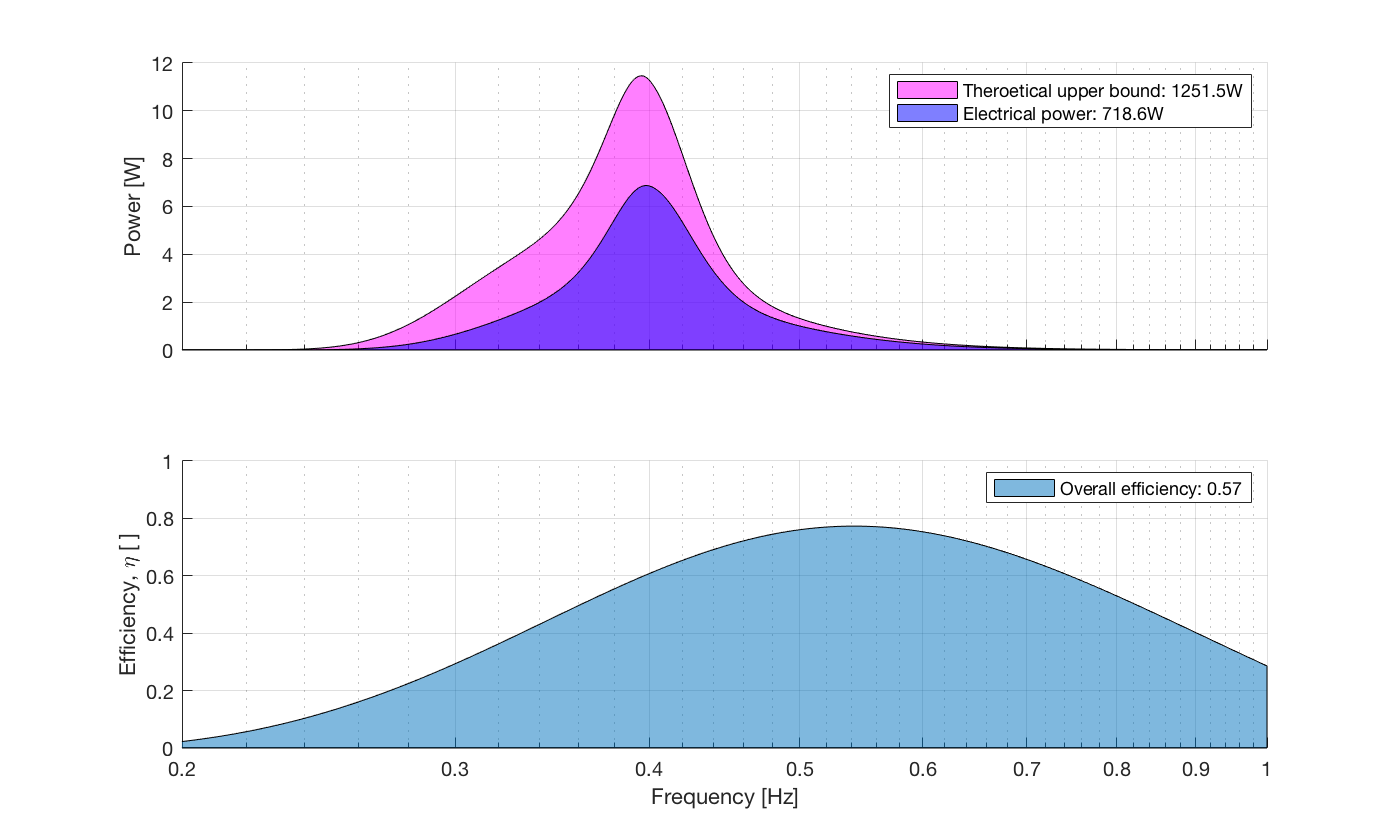

fig2 = figure;
fig2.Position = fig2.Position .* [1 1 1.25 1];

ax(1) = subplot(2,1,1);
hold on
grid on
set(ax(1),'XScale','log')

area(f, P_ub,'facealpha',0.5,'FaceColor','m')
area(f, P_o,'facealpha',0.5,'FaceColor','b')
xlim([0.2,1])
legend(ax(1),...
    sprintf('Theroetical upper bound: %.1fW',P_ub_tot),...
    sprintf('Electrical power: %.1fW',-1*P_tot))
ylabel(ax(1),'Power [W]')
set(ax(1),'xticklabel',[])

ax(2) = subplot(2,1,2);
hold on
grid on
set(ax(2),'XScale','log')
area(f, eta_o, 'facealpha',0.5)
ylim([0 ,1])
xlim([0.2,1])
grid on
ylabel(ax(2),'Efficiency, \eta [ ]')
legend(ax(2),sprintf('Overall efficiency: %.2f',overall_eff))

linkaxes(ax,'x')
xlabel(ax(2),'Frequency [Hz]')